## Data load

% This is the .m file produced by Main.mlx
load("CancerDriverGenesGBM_20240621_222151.mat");

% Load from respective .xlxs file
load("actionableGenes.mat");
load("druggableGenes.mat");

## Calc indexes

topN = 10;
actionableAndDruggable = union(actionableGenes, druggableGenes);

numSamples = length(rankForSamples);
actionableAndDruggableCounts = zeros(numSamples, 1);
actionableCounts = zeros(numSamples, 1);
druggableCounts = zeros(numSamples, 1);

for i = 1:numSamples
    genesInSample = rankForSamples{i}(:, 1);
    topGenes = genesInSample(1:min(topN, length(genesInSample))); 
    actionableAndDruggableCounts(i) = sum(ismember(topGenes, actionableAndDruggable));
    actionableCounts(i) = sum(ismember(topGenes, actionableGenes));
    druggableCounts(i) = sum(ismember(topGenes, druggableGenes));
end

## Plot

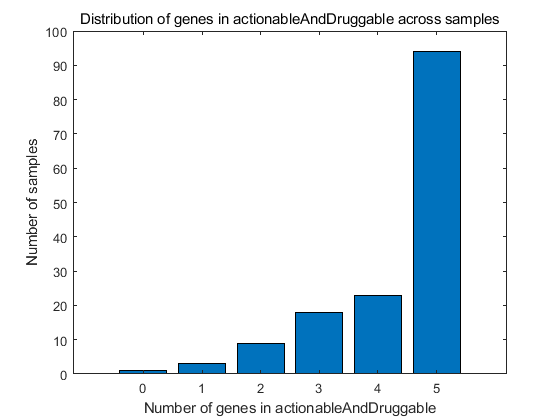


figure;
counts = histcounts(actionableAndDruggableCounts, [0 1 2 3 4 5 inf]); 
bar(0:5, [counts(1:5), sum(counts(6:end))]);
xlabel('Number of genes in actionableAndDruggable');
ylabel('Number of samples');
title('Distribution of genes in actionableAndDruggable across samples');


maxIntersection = min(max(actionableCounts), 5);
actionableCountsDistribution = histcounts(actionableCounts, 0:maxIntersection+1); 
actionableCountsDistribution(end) = sum(actionableCounts >= 5); 

figure;
pieLabels = arrayfun(@(x) sprintf('%d genes', x), 0:maxIntersection, 'UniformOutput', false);
pieLabels{end} = '>=5 genes';
h = pie(actionableCountsDistribution, pieLabels);
title('Distribution of actionable gene intersections across samples');

colormapGreen = [1, 1, 1;
    0.8, 0.898, 0.8;
    0.6, 0.8, 0.6;
    0.4, 0.698, 0.4;
    0.2, 0.6, 0.2;
    0, 0.502, 0;]

colormapGreen =     1.0000    1.0000    1.0000
    0.8000    0.8980    0.8000
    0.6000    0.8000    0.6000
    0.4000    0.6980    0.4000
    0.2000    0.6000    0.2000
         0    0.5020         0


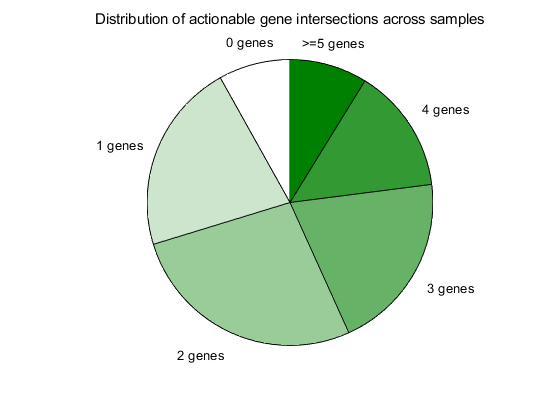

patches = findobj(h, 'Type', 'Patch');
for k = 1:length(patches)
    patches(k).FaceColor = colormapGreen(k, :);
end

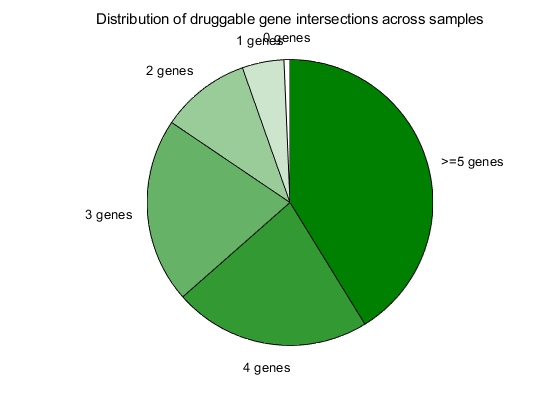


maxIntersection = min(max(druggableCounts), 5);
druggableCountsDistribution = histcounts(druggableCounts, 0:maxIntersection+1); 
druggableCountsDistribution(end) = sum(druggableCounts >= 5); 

figure;
pieLabels = arrayfun(@(x) sprintf('%d genes', x), 0:maxIntersection, 'UniformOutput', false);
pieLabels{end} = '>=5 genes';
h = pie(druggableCountsDistribution, pieLabels);
title('Distribution of druggable gene intersections across samples');

patches = findobj(h, 'Type', 'Patch');
for k = 1:length(patches)
    patches(k).FaceColor = colormapGreen(k, :);
end